# Timing and testing trmm_llnn_unb_var[1-8]

This live script helps you visualize the performance of triangular matrix-matrix multiplication algorithms implemented with FLAMEC

## Time the routines and load the timing data

clear
system( 'make test' )

echo "3 100 1500 100" | ./driver.x > output.m


ans = 0

output

## Check if the answers for the different implementations are correct

max_diff = max( abs( data_unb_var1(:,3) ) )

max_diff = 1.7764e-13

if ( max_diff > 1.0e-12 )
    disp( 'Trouble in paradise?' );
else
    disp( 'All seems to be well' );
end

All seems to be well



max_diff = max( abs( data_unb_var1( :, 3 ) ) )

max_diff = 1.7764e-13

if ( max_diff > 1.0e-12 )
    disp( 'Trouble in paradise' );
else
    disp( 'All seems to be well' );
end

All seems to be well


## Plot the timing data

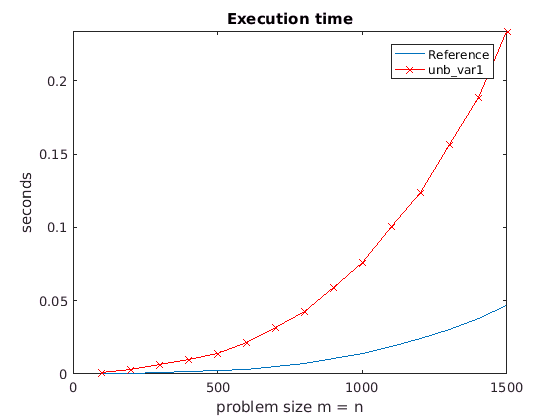

plot( data_ref( :, 1 ), data_ref( :, 2 ), '-' )
hold on
plot( data_unb_var1(:,1), data_unb_var1(:,2), 'x-r' );

legend( 'Reference', ...
    'unb\_var1' );

axis( [0,max(data_unb_var1(:,1)), 0,max(data_unb_var1(:,2)) ] )  % set the range of the axes

title( 'Execution time' )
xlabel( 'problem size m = n' )
ylabel( 'seconds' )

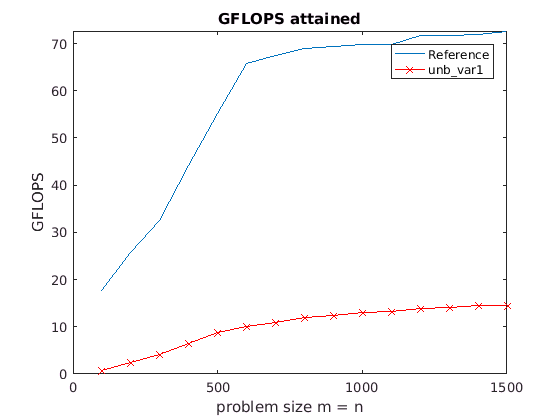

% plot the GFLOPS attained

figure     % start new figure
hold off

% create an array of the number of flops executed in billions
gflops_ref = data_ref(:,1).^3 * 1.0e-9;


plot( data_ref( :, 1 ), gflops_ref./data_ref( :, 2 ), '-' )
hold on

gflops_unb_var1 = data_unb_var1(:,1).^3 * 1.0e-9;
plot( data_unb_var1(:,1), gflops_unb_var1./data_unb_var1(:,2), 'x-r' );

legend( 'Reference', ...
    'unb\_var1' );

axis( [0,max(data_unb_var1(:,1)), 0,max(gflops_ref./data_ref(:,2)) ] )  % set the range of the axes

title( 'GFLOPS attained' )
xlabel( 'problem size m = n' )

ylabel( 'GFLOPS' )